  Name        Size                  Bytes  Class    Attributes

  a         371x1000x3            1113000  uint8              



  Name        Size               Bytes  Class    Attributes

  b         371x1000            371000  uint8              



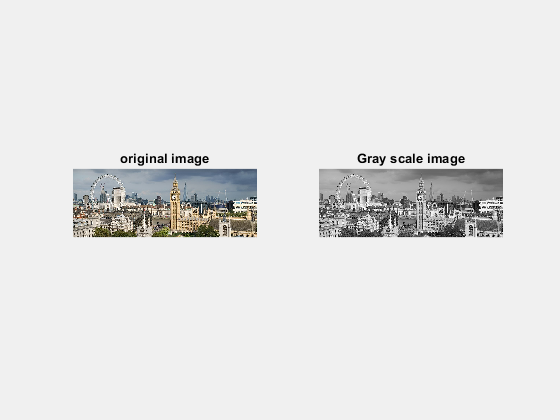

  Name        Size               Bytes  Class      Attributes

  c         371x1000            371000  logical              



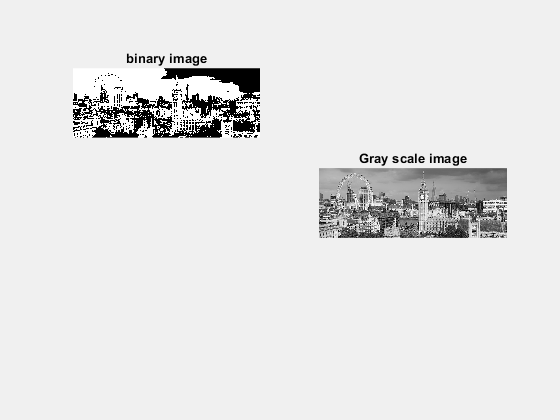

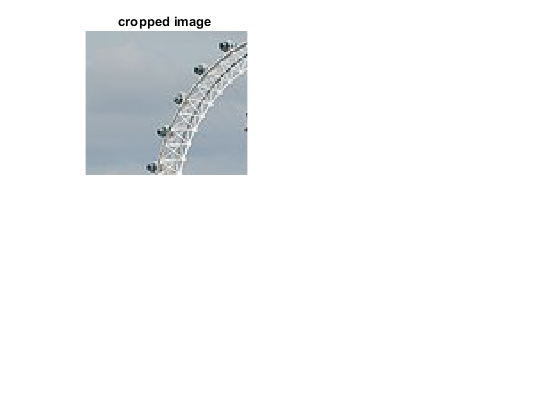

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

% Experiment-1
% To perform basic img processing opr.

%converting RGB to grayscale
a=imread('E:\Study\DIP\Lab_exp\london.jpg');

b=rgb2gray(a);

% whos is used to makeout what r the diff 
% attributes of this particular img (img dimension, 
% class in which it has been saved #rows, #colum,
% unsigned/signed, double? or not)

whos a 
whos b
subplot(1,2,1)
imshow(a);
title('original image')
subplot(1,2,2)
imshow(b)
title('Gray scale image')

%converting into binary
c=imbinarize(b);
whos c 
subplot(2,2,1)
imshow(c);
title('binary image')

% % % % % cropping of image 
a=imread('E:\Study\DIP\Lab_exp\london.jpg');
d=imcrop(a,[60 40 90 80]);
figure;
subplot(2 ,2, 1);
imshow(d);
title('cropped image ')

% %cropping of image manually
% a=imread('E:\Study\DIP\Lab_exp\london.jpg');
% [J,rect]= imcrop(a);
% subplot(2,2,1)
% imshow ([J,rect])

% title('cropped image')

%resizing of image 
a=imread('E:\Study\DIP\Lab_exp\london.jpg');
subplot(2,2,2)
imshow(a);
title('original image');
b=imresize(a,[256,256]);
subplot(2,2,3)
imshow(b);
title('resized image')



